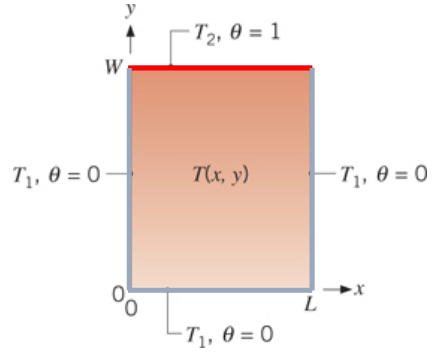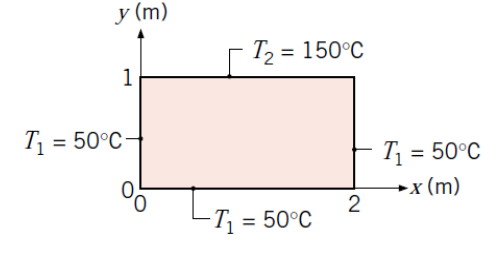

clear all
clf
syms theta(x,y) x y T(x,y) T_diff_x(x,y) T_diff_y(x,y)
T2 = 150 + 273.15;
T1 = 50 + 273.15;
n_end = 30; % antal led på polynomiet
W = 1; %højde
L = 2; %brede
sums = 0;


Equations

for n = 1:n_end
    sum_n = ((-1)^(n+1) + 1) / n * sin(n * pi * x / L) * sinh(n*pi*y/L) / sinh(n*pi*W/L);
    sums = sums + sum_n;
end

theta(x,y) = 2/pi * sums;
T(x,y) = T2 - T1*theta(x,y) + T2*theta(x,y);
% eq = theta1 == (Ttest - T2)/(T2-T1);
% Ttest = solve(eq, Ttest)

T_diff_x(x,y) = diff(T(x,y), x);
T_diff_y(x,y) = diff(T(x,y), y);

Mesh creation

scalar_filed_size = 20;  % change sizes here
x_lin = linspace(0,L,scalar_filed_size);
y_lin = linspace(0,W,scalar_filed_size);

for i = 1:scalar_filed_size
    for j = 1:scalar_filed_size
        scalar_field(i,j) = T(x_lin(i),y_lin(j));
        DX(i,j) = T_diff_x(x_lin(i),y_lin(j));
        DY(i,j) = T_diff_y(x_lin(i),y_lin(j));
    end
end

DX
DY
[X,Y] = meshgrid(x_lin,y_lin);
%rotation of the grid to mach figure
X = X'; 
Y = Y';

Plot

q = quiver(X,Y,DX,DY);
hold on
contour(X,Y,scalar_field)
title('Contour plot of temperature distrubution')
ylabel('y(m)')
xlabel('x(m)')
% q.ShowArrowHead = 'off';
% q.Marker = '.';
% q.AutoScaleFactor(0.5)
% legend(Location="southeast")
hold off

clear all
clf
syms theta(x,y) x y T(x,y) T_diff_x(x,y) T_diff_y(x,y)
T2 = 150 + 273.15;
T1 = 50 + 273.15;
n_end = 40; % antal led på polynomiet
W = 1; %højde
L = 2; %brede
sums = 0;

% Equations
for n = 1:n_end
    sum_n = ((-1)^(n+1) + 1) / n * sin(n * pi * x / L) * sinh(n*pi*y/L) / sinh(n*pi*W/L);
    sums = sums + sum_n;
end

theta(x,y) = 2/pi * sums;
T(x,y) = T2 - T1*theta(x,y) + T2*theta(x,y);
% eq = theta1 == (Ttest - T2)/(T2-T1);
% Ttest = solve(eq, Ttest)

T_diff_x(x,y) = diff(T(x,y), x);
T_diff_y(x,y) = diff(T(x,y), y);

% Mesh creation
scalar_field_size = 50;  % change sizes here
x_lin = linspace(0, L, scalar_field_size*2);
y_lin = linspace(0, W, scalar_field_size);

% Initialize matrices
scalar_field = zeros(scalar_field_size);
DX = zeros(scalar_field_size);
DY = zeros(scalar_field_size);

% Populate scalar_field, DX, and DY
for i = 1:scalar_field_size
    for j = 1:scalar_field_size
        scalar_field(i, j) = double(T(x_lin(i), y_lin(j)));
        DX(i, j) = double(T_diff_x(x_lin(i), y_lin(j)));
        DY(i, j) = double(T_diff_y(x_lin(i), y_lin(j)));
    end
end

% Create heatmap using imagesc
figure;
imagesc(x_lin, y_lin, flip(scalar_field'));
colorbar; % Add colorbar for the heatmap
title('Heatmap of temperature distribution');
xlabel('x(m)');
ylabel('y(m)');